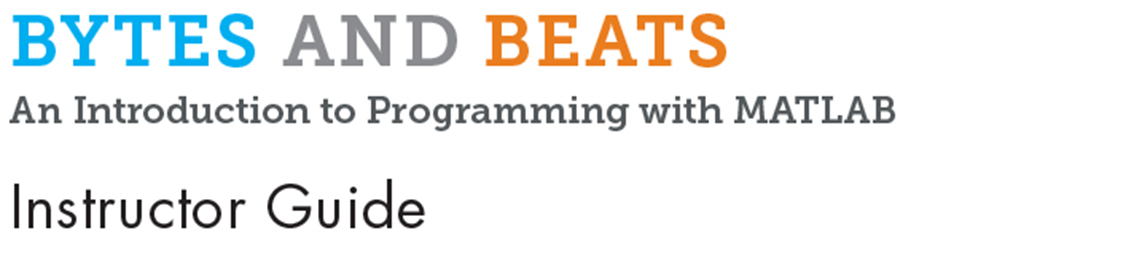

# Module 12: Creating a Virtual Theremin

**Prerequisite Domain Knowledge:** Functions, Loops, Figures, Callbacks

**Expected Completion Time: **50 minutes

## Virtual Theremin

*Expected Duration: 25 minutes*

### Learning Objectives

- Combine the use of several basic programming constructs.

- Use continuously changing window property in a callback function.

### Motivation

In this activity, students will create a musical instrument – a virtual theremin.

### Materials

- MATLAB®

- Worksheet "Virtual Theremin"

### Solution

 
open VirtualTheremin_solution.mlx

### Steps

- Briefly open the Keyboard Piano activity and revise *uifigure* window and callback function concepts.

 
open KeyboardPiano_solution.mlx

- Get the students excited about making their second musical instrument –a theremin. Show them a video of the theremin.

- [https://youtu.be/-QgTF8p-284](https://youtu.be/-QgTF8p-284)

- The theremin produces a different pitch and amplitude based on the distance of the hands from the antennas. Since we can't make an actual theremin, we will create a virtual one, where based on where we place our mouse pointer, the theremin will produce a different pitch and amplitude.

Ask the students to get the template Live Script "VirtualTheremin.mlx"

 
open VirtualTheremin.mlx

This script has three sections. The first section creates a figure window just like we had for the piano. The inputs to the `uifigure` function are used to set different properties of this window, as we have seen before.

Our virtual theremin will change pitch and amplitude based on the horizontal and vertical location of the mouse pointer (cursor) on this figure. Recall how we made the piano using the `'WindowKeyPressFcn'` callback. This callback function executed every time you pressed a key on the keyboard. 

- Similarly, for this activity, we will use the `'WindowButtonMotionFcn'`callback of the figure. Ask the students to guess when this callback function will get executed.

- Ans - When you move the mouse pointer (cursor) over the figure.

Go over to the next section of code with the students and discuss:

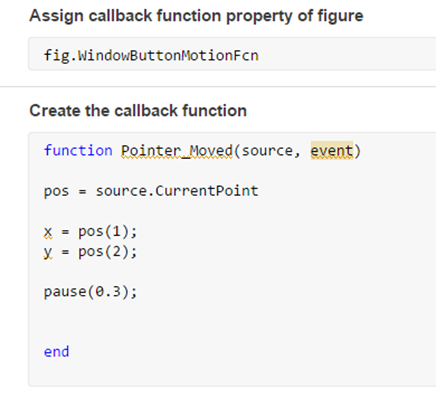

The next line is supposed to assign the figure's `'WindowButtonMotionFcn'.` In the next section, we have written a function called `'Pointer_Moved'`. This is the function we want to execute when the mouse pointer is moved. 

- Tell the students to assign the `Pointer_Moved` function to the `WindowButtonMotionFcn `property using the '@' notation. You can refer to the "KeyboardPiano.mlx" script to recall the syntax.

The `'Pointer_Moved'`function has two inputs: `source` and `event `just like the piano's` Key_Down `function`.`

- The source is the uifigure window, to which this callback is linked. Inside the function, we are creating a variable `pos` to store the current location of the mouse pointer. This information is taken from the `CurrentPoint` property of the `source` (uifigure). 

- Tell the students to run the entire script. A figure window should open. As you move your cursor over this window, you should see numbers displayed in the **Command Window**. These numbers indicate the current position of the mouse pointer within the figure. The first number tells the location in horizontal direction and the second number tells the location in the vertical direction. 

Distribute the worksheet "Virtual Theremin" to the students. 

First, we want to find the minimum and maximum x and y values. To do so, they must try to find the positions of the four corner points in the figure by moving their cursor over them. Ask the students to fill in the corner points in the figure given. The four points will have the values:

- [1,1]; [1, 500]; [500, 500] and [500, 1] 

- going clock-wise starting from bottom left.

- And so, the minimum x and y values will be:

-     xmin = 1

-     ymin = 1

-     xmax = 500

-     ymax = 500

- Let the students spend some time moving their pointer over the figure and understanding how the position values change as the mouse pointer moves. We will use these numbers to change sounds as we move the mouse pointer.

Tell the students to close the figure window. They will now write code inside the callback function to play different sounds for different horizontal positions, using `sineSound`function. Ask the students how they might do that. 

- Ans – Use '`if`' statement to check value of `x` and play a sound.

Before writing the code, the students must complete the table in the worksheet which will help them plan the code.

- At this point, tell the students to complete the first table for X.

In the first column, they will enter the minimum and maximum x values found previously (1 and 500). Then, they can divide this range by picking any two numbers in between. For e.g., 200.

- In the second column, they will pick a frequency of sound for each range of X values.  For e.g., 440 Hz.

Finally, in the third column, they will complete the statements based on the first two columns. This is sentence representation of the code they will write. For e.g., if x is between 1 and 200, Play sineSound(440)

The completed worksheet should look something like this (example values used here):

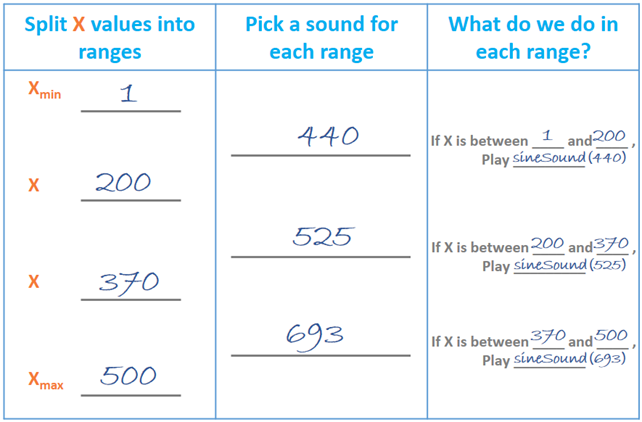

The students can now try to complete the code after the pause statement inside the function. Get them started by showing them the first `'if'` statement on your screen. Each sound should be played for 0.6 seconds. 

This is what the code should look like at this point. The range limits and sound frequencies may be different based on the worksheet. 

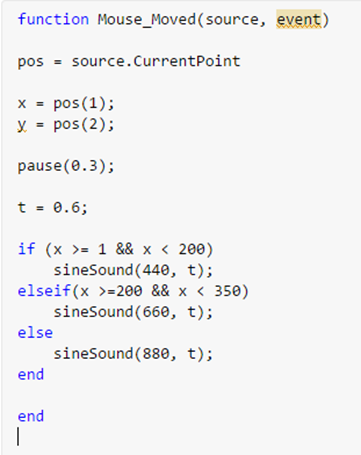

- Some students may also use multiple `'if' `statements instead of `'elseif' `and `'else' `statements. 

When the students run their script, moving the pointer horizontally over the figure should produce a change in sound frequency.

Finally, students can also change the color of the figure window for different sounds by changing the `source.Color` property, like we did for the piano activity.

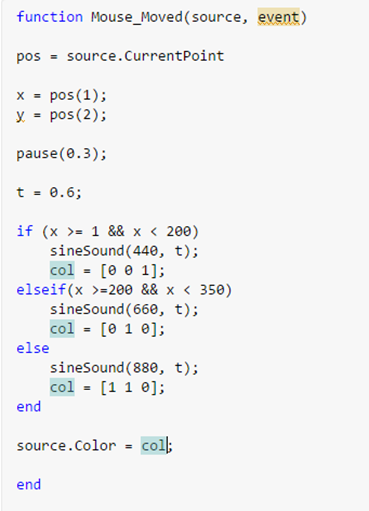

So far, we are changing the frequency as we move the pointer horizontally. But, we are not changing the amplitude (or volume) yet. The change in frequency is also not continuous. 

- This is what we will do in a later module. At this point, allow the students to experiment with their code and try our different sounds, colors, durations etc. They can also break up the code in more than three sections. 

**NOTE –** If using MATLAB Online, students may sometimes see an error dialog while sound is playing. This is because, too many sounds cannot be played simultaneously on MATLAB Online unlike the Desktop. Make sure that there is a pause statement in the callback function. If the error is frequent, increase the duration of pause slightly. If it is infrequent and rare, click OK and move the pointer slowly.

## Customizing the Theremin

*Expected Duration: 25 minutes*

### Learning Objectives

- Use callback function inputs to control sound parameters and make it continuously changing.

### Motivation

A real theremin's pitch and volume change continuously as the hands move. We want to achieve a similar effect as we move the pointer over the window.

### Materials

- MATLAB

- Worksheet "Customizing the Theremin"

### Steps

We started building the theremin in the previous activity. However, it is not complete yet. So far, the frequency change in horizontal direction is not continuous and we are not changing the amplitude in the vertical direction. Ask the students to think about:

- How they would make the sound's frequency change continuously

- How they would make the amplitude change with vertical motion of pointer

- The students have seen that the position (x and y) is continuously changing as we move the mouse pointer over the window. Tell them that we can make the value of frequency dependent on x and the amplitude dependent on y. This way, the frequency and amplitude will also change continuously.

So far, we used the `sineSound` function with two inputs: frequency and duration. The `sineSound` function can also take a third input which specifies the amplitude. This number should be between 0 and 1. Tell the students to try these commands in the **Command Window** one at a time:

We will now need to work out the conversion from x and y to frequency and amplitude. 

Distribute the worksheet "Customizing the Theremin" to the students. 

Explain that we want the frequency to go from a small number up to 2000Hz and we want the amplitude to go from a number close to 0 to 1. Since x and y go from 1 to 500, we must work out a scalar operation to obtain frequency and amplitude from them.

- Once the students have completed the Worksheet, they will now have the two lines of code required:

Tell the students to open the starter code by using this command:

 
open VirtualTheremin_continuous.mlx

- This is the same place we started yesterday. They can now enter the two lines of code toward the bottom of the callback function. 

Now, they must add code to play the sound using` sineSound `function. Give them a hint that they need to use `freq, t `and` amp `as inputs to the function. They must also be careful about the order of the inputs as it matters.

Help the students to complete this function by giving hints. Here is what the code will look like at this stage:

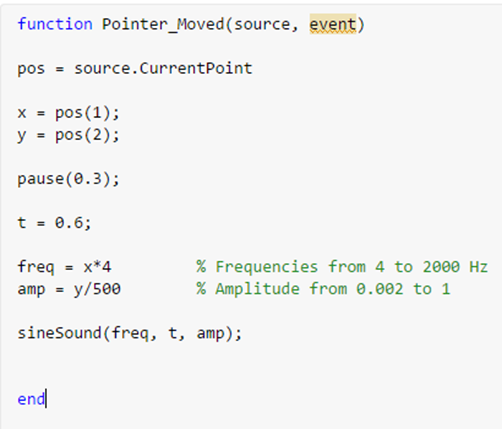

Students can now run the code and test it by moving the pointer in both directions over the figure. Since we have added a pause statement, moving the cursor slowly will give it a more continuous effect. 

Finally, to customize their instrument further, students can make the color of the window change continuously along with the sound. Ask them how they would do it. 

- Hint – Color is specified by three numbers between 0 and 1. 

- Students can make one or more of the three numbers dependent on x and/or y. Here is an example code that can be entered in the function:

- Here, we have fixed the green value to 0.8 and made red and blue dependent on x and y. Like the operation for amplitude, we divide by 500 to convert to a number between 0 and 1.

© COPYRIGHT 2024 by The MathWorks®, Inc.